## MEEM 4775 Homework 1

Ross Smyth

2020-09-05

clc, clear, close all

### 1a)

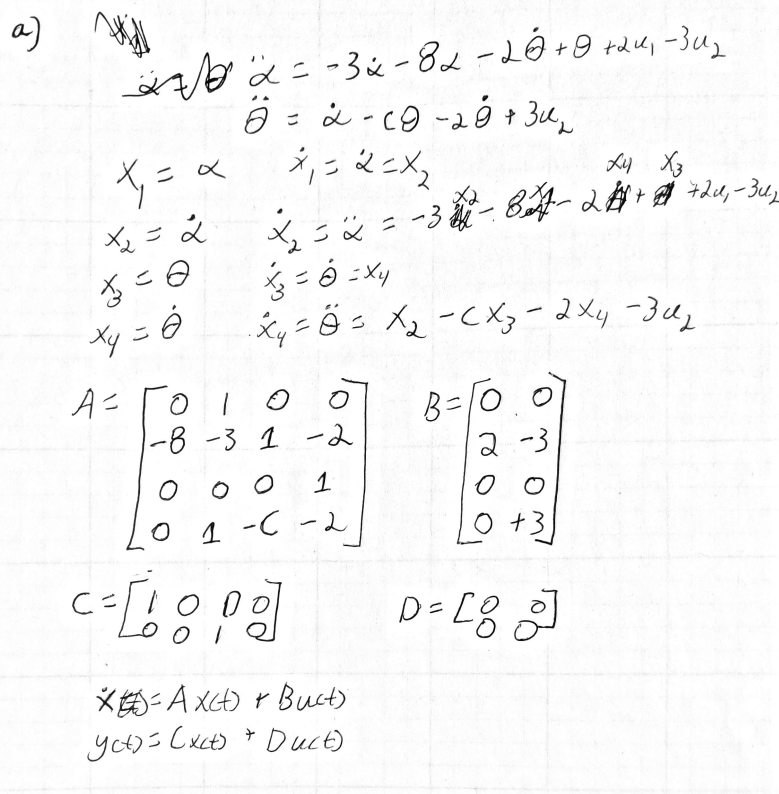

### 1b)

c = 3;
A = [0,  1, 0,  0;
    -8, -3, 1, -2;
     0,  0, 0,  1; 
     0,  1 -c, -2];
B = [0,  0;
     2, -3;
     0,  0;
     0,  3;];
C = [1, 0, 0, 0;
     0, 0, 1, 0];
D = [0, 0;
     0, 0];

state_space = ss(A, B, C, D);
transfer_functions = tf(state_space)


transfer_functions =
 
  From input 1 to output...
               2 s^2 + 4 s + 6
   1:  --------------------------------
       s^4 + 5 s^3 + 19 s^2 + 24 s + 24
 
                2 s - 2.22e-16
   2:  --------------------------------
       s^4 + 5 s^3 + 19 s^2 + 24 s + 24
 
  From input 2 to output...
              -3 s^2 - 12 s - 6
   1:  --------------------------------
       s^4 + 5 s^3 + 19 s^2 + 24 s + 24
 
               3 s^2 + 6 s + 24
   2:  --------------------------------
       s^4 + 5 s^3 + 19 s^2 + 24 s + 24
 
Continuous-time transfer function.



### 1c)

eigenvalues = eig(A)

eigenvalues =   -1.7976 + 2.9509i
  -1.7976 - 2.9509i
  -0.7024 + 1.2316i
  -0.7024 - 1.2316i


poles = pole(transfer_functions)

poles =   -1.7976 + 2.9509i
  -1.7976 - 2.9509i
  -0.7024 + 1.2316i
  -0.7024 - 1.2316i
  -1.7976 + 2.9509i
  -1.7976 - 2.9509i
  -0.7024 + 1.2316i
  -0.7024 - 1.2316i


eigvalue_concate = [eigenvalues; eigenvalues]

eigvalue_concate =   -1.7976 + 2.9509i
  -1.7976 - 2.9509i
  -0.7024 + 1.2316i
  -0.7024 - 1.2316i
  -1.7976 + 2.9509i
  -1.7976 - 2.9509i
  -0.7024 + 1.2316i
  -0.7024 - 1.2316i


round(eigvalue_concate,13) == round(poles, 13)

ans = 8×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1


The eigvalues of the A matrix and the poles are not exactly the same, but they are down to 13 decimals. I am confident that the discrepancy is due to floating-point arithmetic leading to errors in the numbers, and not that they are actually different. Because this the poles are the eigenvalues of the A matrix but with them repeated one more time for a total of four repitions. This makes sense as the poles of the system define the inherent dynamics of a system, and so that should be the same for all four of the transfer functions.

### 1d)

numer = transfer_functions.Numerator{1};
denom = transfer_functions.Denominator{1};

A = [-denom(2:5); eye(length(denom) - 1)];
A(end, :) = []

A =    -5.0000  -19.0000  -24.0000  -24.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B = [1; zeros(length(A) - 1, 1)]

B =      1
     0
     0
     0


C = numer(2:5)

C =          0    2.0000    4.0000    6.0000


D = numer(1)

D = 0

control_canon = ss(A, B, C, D);

### 1e)

tf_test = tf2ss(numer, denom)

tf_test =    -5.0000  -19.0000  -24.0000  -24.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


tf_test == A

ans = 4×4 logical array
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1


The output of the tf2ss function outputs the same state matrix as determined above to find the controllable canonical form. It most likely does the calculation in the same or similar way as done above in 1d.

### 2a)

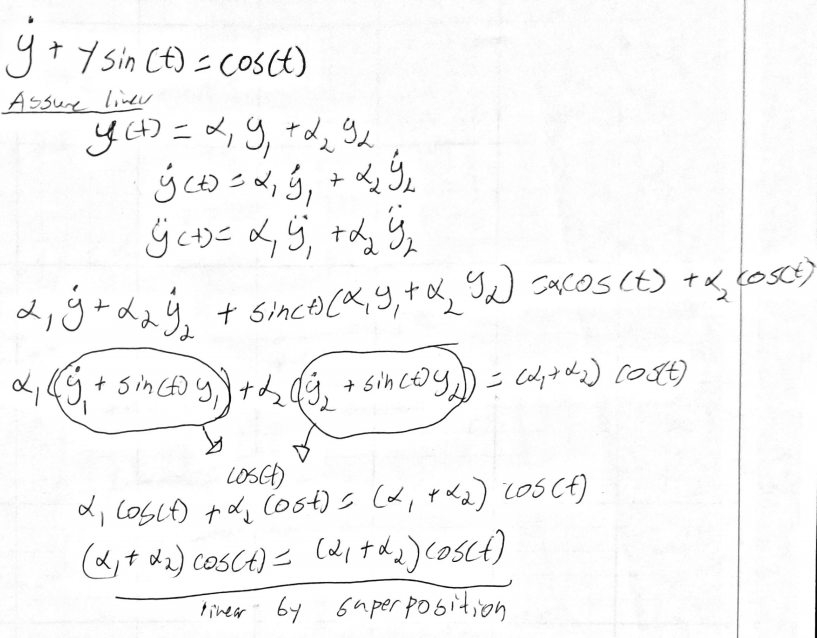

### 2b)

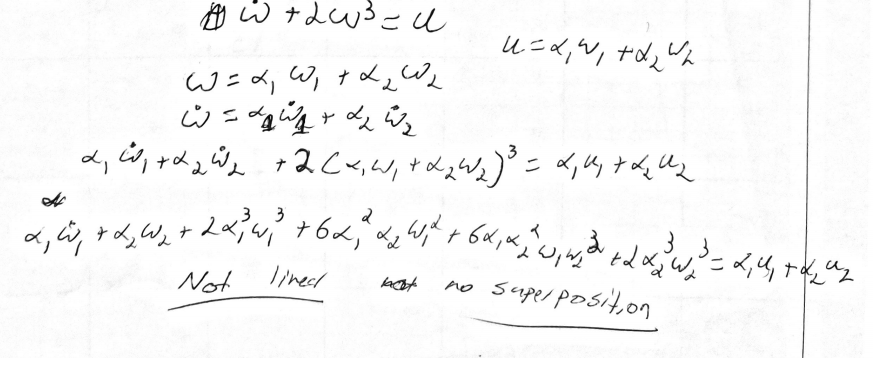

### 2c)